G = tf(1245.09,[1 77 5259 0 0])


G =
 
           1245
  -----------------------
  s^4 + 77 s^3 + 5259 s^2
 
Continuous-time transfer function.
Model Properties


H = feedback(G,1)


H =
 
               1245
  ------------------------------
  s^4 + 77 s^3 + 5259 s^2 + 1245
 
Continuous-time transfer function.
Model Properties


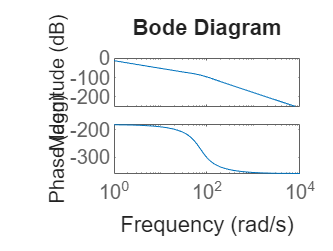

bode(G)

% Controller
Kp = 10

Kp = 10

Kd = 100

Kd = 100

controller = pid(Kp,0,Kd)


controller =
 
             
  Kp + Kd * s
             

  with Kp = 10, Kd = 100
 
Continuous-time PD controller in parallel form.
Model Properties


% new open loop with the controller
openloop = G * controller


openloop =
 
   1.245e05 s + 1.245e04
  -----------------------
  s^4 + 77 s^3 + 5259 s^2
 
Continuous-time transfer function.
Model Properties


% new closed loop 
closedloop = feedback(openloop,1)


closedloop =
 
               1.245e05 s + 1.245e04
  -----------------------------------------------
  s^4 + 77 s^3 + 5259 s^2 + 1.245e05 s + 1.245e04
 
Continuous-time transfer function.
Model Properties


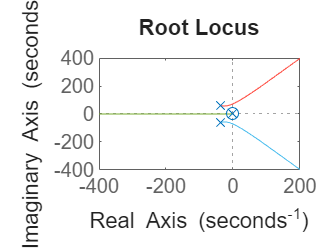

rlocus(openloop)

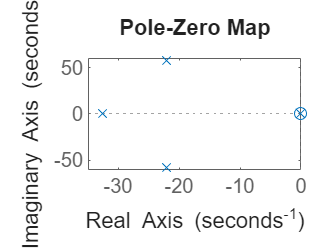

pzmap(closedloop)

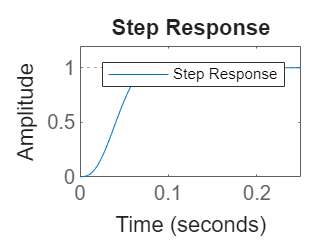

% step response with overshoot < 20%  and settling time < 2.5
step(closedloop)
legend('Step Response')
legend show

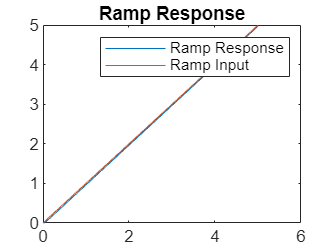

% Input ramp
t = 0:0.001:5;
ramp = t;
[y_ramp] = lsim(closedloop, ramp, t);
plot(t,y_ramp)
hold on
plot(t,ramp)
title('Ramp Response')
legend('Ramp Response','Ramp Input')
legend show
hold off

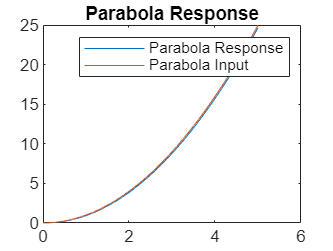

% Input parabola
parabola = t.^2;
[y_parabola] = lsim(closedloop,parabola,t);
plot(t,y_parabola)
hold on
plot(t,parabola)
title ('Parabola Response')
legend('Parabola Response','Parabola Input')
legend show
hold off

% Stability Check

pzmap(closedloop)


% System Type
openloop % sys type 2


openloop =
 
   1.245e05 s + 1.245e04
  -----------------------
  s^4 + 77 s^3 + 5259 s^2
 
Continuous-time transfer function.
Model Properties


% Steady State Error Calculations

% Define time vector and inputs
t = 0:10:100000;         % Time vector
step_input = ones(size(t));     % Step input
ramp_input = t;                % Ramp input
parabolic_input = t.^2;        % Parabolic input

% Simulate outputs
y_step = lsim(closedloop, step_input, t);          % Step response
y_ramp = lsim(closedloop, ramp_input, t);          % Ramp response
y_parabola = lsim(closedloop, parabolic_input, t); % Parabolic response

% Compute steady-state error
ess_step = abs(1 - y_step(end));             % Steady-state error for step input
ess_ramp = abs(t(end) - y_ramp(end));        % Steady-state error for ramp input
ess_parabolic = abs(t(end)^2 - y_parabola(end)); % Steady-state error for parabolic input

disp('Numerical Steady-State Errors:');

Numerical Steady-State Errors:


disp(['Step: ', num2str(ess_step)]);

Step: 1.1102e-16


disp(['Ramp: ', num2str(ess_ramp)]);

Ramp: 0


disp(['Parabolic: ', num2str(ess_parabolic)]);

Parabolic: 0.49178


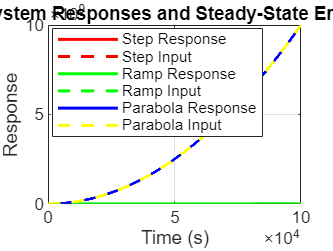


% Plot responses
figure;
plot(t, y_step, 'r', t, step_input, 'r--', 'LineWidth', 1.5); hold on;
plot(t, y_ramp, 'g', t, ramp_input, 'g--', 'LineWidth', 1.5);
plot(t, y_parabola, 'b', t, parabolic_input, 'y--', 'LineWidth', 1.5);
legend('Step Response', 'Step Input', 'Ramp Response', 'Ramp Input', ...
       'Parabola Response', 'Parabola Input', 'Location', 'best');
xlabel('Time (s)');
ylabel('Response');
title('System Responses and Steady-State Errors');
grid on;
hold off

stepinfo(closedloop)

ans = struct with fields:
         RiseTime: 0.0432
    TransientTime: 0.1515
     SettlingTime: 0.1515
      SettlingMin: 0.9201
      SettlingMax: 1.0251
        Overshoot: 2.5124
       Undershoot: 0
             Peak: 1.0251
         PeakTime: 0.0852


rlocus(openloop)

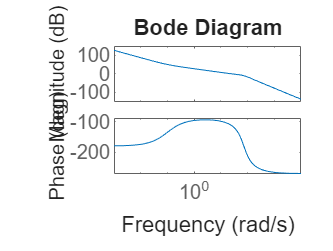

bode(openloop)

% Define the open-loop transfer function G(s)
s = tf('s');
G = tf(1245.09,[1 77 5259 0 0]);

% Define the compensators
% Lead compensator (example values)
K_lead = 350; 
z_lead = 0.1; % Zero of the lead compensator
p_lead = 10; % Pole of the lead compensator
C_lead = K_lead * (s + z_lead)/(s + p_lead);
Openloop = C_lead*G;

% Closed-loop transfer functions
T_lead = feedback(C_lead * G, 1);

% Time vector for simulation
t = 0:0.1:100;

% Inputs: step, ramp, and parabolic
step_input = ones(size(t));          % Step input
ramp_input = t;                      % Ramp input
parabola_input = t.^2;               % Parabolic input

% Simulate the system response for each input
[y_lead_step, t_out] = lsim(T_lead, step_input, t);
stepinfo(T_lead)

ans = struct with fields:
         RiseTime: 0.1722
    TransientTime: 0.8434
     SettlingTime: 0.8434
      SettlingMin: 0.9098
      SettlingMax: 1.1955
        Overshoot: 19.5538
       Undershoot: 0
             Peak: 1.1955
         PeakTime: 0.4146


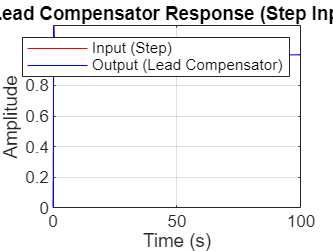


% Plot step input and output for Lead, Lag, Lead-Lag compensators
figure;
plot(t, step_input, 'r', 'DisplayName', 'Input (Step)');
hold on;
plot(t_out, y_lead_step, 'b', 'DisplayName', 'Output (Lead Compensator)');
xlabel('Time (s)');
ylabel('Amplitude');
title('Lead Compensator Response (Step Input)');
legend;
grid on;

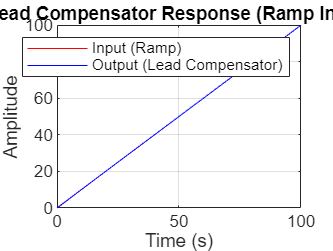


% Now we plot for Ramp input
[y_lead_ramp, ~] = lsim(T_lead, ramp_input, t);

figure;
plot(t, ramp_input, 'r', 'DisplayName', 'Input (Ramp)');
hold on;
plot(t_out, y_lead_ramp, 'b', 'DisplayName', 'Output (Lead Compensator)');
xlabel('Time (s)');
ylabel('Amplitude');
title('Lead Compensator Response (Ramp Input)');
legend;
grid on;

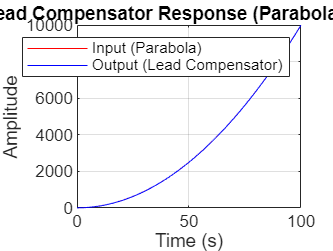



% Plot for Parabolic input
[y_lead_parabola, ~] = lsim(T_lead, parabola_input, t);

figure;
plot(t, parabola_input, 'r', 'DisplayName', 'Input (Parabola)');
hold on;
plot(t_out, y_lead_parabola, 'b', 'DisplayName', 'Output (Lead Compensator)');
xlabel('Time (s)');
ylabel('Amplitude');
title('Lead Compensator Response (Parabola Input)');
legend;
grid on;
hold off

% Root locus& Bode on new system
rlocus(openloop)

bode(openloop)